syms x real
f1 =@(x) exp(3*x).*sin(2*x); % define the first eq.
f1(x)

$$ans = \sin\left(2\,x\right)\,{\mathrm{e}}^{3\,x}$$

f2 =@(x) x.*sin(x.^2); % define the second eq.
f2(x)

$$ans = x\,\sin\left(x^{2}\right)$$

f1_int = matlabFunction(int(f1(x))); % f1 analytic integration
f1_int(x)

$$ans = -\frac{{\mathrm{e}}^{3\,x}\,\left(2\,\cos\left(2\,x\right)-3\,\sin\left(2\,x\right)\right)}{13}$$

f2_int = matlabFunction(int(f2(x))); % f2 analytic integration
f2_int(x)

$$ans = -\frac{\cos\left(x^{2}\right)}{2}$$

clear x
format long
a1 = 0; b1 = pi/4; % define the integration bounderies.
a2 = 0; b2 = pi;
epsilon = 1e-6;
exacat_sol_1 = f1_int(b1)-f1_int(a1); %find problems exact solutions by I(b)-I(a)
exacat_sol_2 = f2_int(b2)-f2_int(a2);

%initilaize varabiles for logs
Err_vec = [0;0]; 
CompTime_vec = [0;0];
Intgral_Err_vec = [0;0];
Intgral_CompTime_vec = [0;0];
CompTime_num = 1; max_n = 3;

format long
for n = 1:max_n
    % solve and masure time for the first problem with our implementation.
    tic
    for k =1 : CompTime_num
        I1 = AdaptQuad(f1,a1,b1,n,epsilon);
    end
    t1 = toc/CompTime_num;
    % solve and masure time for the second problem with our implementation.
    tic
    for k =1 : CompTime_num
        I2 = AdaptQuad(f2,a2,b2,n,epsilon);
    end
    t2 = toc/CompTime_num;
    % masure time for Matlab's Integral function
    tic
    for k =1 : CompTime_num
        Intgral_I1 = integral(f1,a1,b1,'RelTol',epsilon);
    end
    Intgral_t1 = toc/CompTime_num;
    tic
    for k =1 : CompTime_num
        Intgral_I2 = integral(f2,a2,b2,'RelTol',epsilon);
    end
    Intgral_t2 = toc/CompTime_num;
    
   % save abs. relative errors and computong times.
   Err_vec(1,n) = abs(exacat_sol_1 - I1)/exacat_sol_1;
   Err_vec(2,n) = abs(exacat_sol_2 - I2)/exacat_sol_2;
   CompTime_vec(:,n) = [t1;t2];
   
   Intgral_Err_vec(1,n) = abs(exacat_sol_1 - Intgral_I1)/exacat_sol_1;
   Intgral_Err_vec(2,n) = abs(exacat_sol_2 - Intgral_I2)/exacat_sol_2;
   Intgral_CompTime_vec(:,n) = [Intgral_t1;Intgral_t2];
end

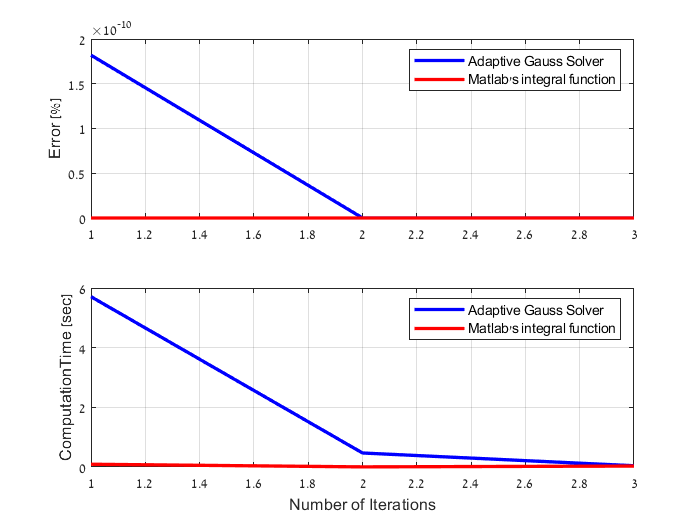

set(0, 'DefaultLineLineWidth', 2);
figure
subplot (2,1,1)
plot([1:max_n],Err_vec(1,:)*100,'b')
hold on
plot([1:max_n],Intgral_Err_vec(1,:)*100,'r')
hold off
legend ('Adaptive Gauss Solver','Matlab''s integral function')
grid on
ylabel 'Error [%]'
subplot (2,1,2)
plot([1:max_n],CompTime_vec(1,:),'b')
hold on
plot([1:max_n],Intgral_CompTime_vec(1,:),'r')
hold off
legend ('Adaptive Gauss Solver','Matlab''s integral function')
grid on
ylabel 'ComputationTime [sec]'
xlabel 'Number of Iterations'

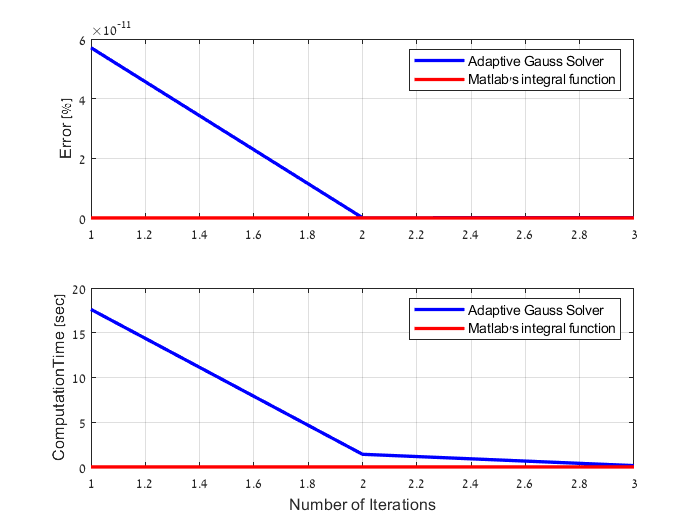



figure
subplot (2,1,1)
plot([1:max_n],Err_vec(2,:)*100,'b')
grid on
hold on
plot([1:max_n],Intgral_Err_vec(2,:)*100,'r')
hold off
legend ('Adaptive Gauss Solver','Matlab''s integral function')
ylabel 'Error [%]'
subplot (2,1,2)
plot([1:max_n],CompTime_vec(2,:),'b')
grid on
hold on
plot([1:max_n],Intgral_CompTime_vec(2,:),'r')
hold off
legend ('Adaptive Gauss Solver','Matlab''s integral function')
ylabel 'ComputationTime [sec]'
xlabel 'Number of Iterations'